# Figure 5: Current Analysis of Figure 4

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030];
S_IItest = [0.08  0.12  0.16  0.20];
Panel2 = length(S_EEtest); Panel1 = length(S_IItest);
S_ElgnInd = 3;
S_IlgnInd = 2; % $(seq 2 4)
rI_L6Ind = 3;  % 3 6

Fig5A = figure('Name','Figure5A_E','units','normalized','outerposition',[0 0 .75 1]);
ha1 = tight_subplot(Panel1,Panel2,[.01 .015],[.12 .08],[.08 .02]);
% Set caxis first
ColorLim = [14.5 12 10 8  7 
            19   18 17 15 14];
              
for S_EEInd = 1:length(S_EEtest)
    for S_IIInd = 1:length(S_IItest)
        % DEtermine dependent parameters
        S_EE = S_EEtest(S_EEInd);
        S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
        S_Elgn=S_Elgntest(S_ElgnInd);
        
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
            S_EE,     S_II,     S_ElgnInd,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        FrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        FrE(FrE<=0) = 0;
        FrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        FrI(FrE<=0) = 0;
        mVE = squeeze(ContourData_7D.mV_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        mVE(FrE<=0) = 0;
        mVI = squeeze(ContourData_7D.mV_NoFix(2,:,: ));
        mVI(FrE<=0) = 0;
        Blowup = squeeze(ContourData_7D.FailIndi(:,: ));
        
        GoodAreaInd = FrE>=3 & FrE<=5   & ...
            FrI./FrE    >=3   &   FrI./FrE    <=4.25;
        % Take all values from the field
        unpackStruct(ContourData_7D);
        E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
        [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
        E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
        
        I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
        [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
        I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
        
        N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
        N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));
        
        % A few Ss is indexed to S_IE; and Ref on Fr; so need to prepared in advance
        S_EIMat = repmat(S_EItest',1,length(S_IEtest));
        S_IEMat = repmat(S_IEtest, length(S_EItest),1);
        S_IL6 = 1/3*S_IEMat;
        E_Refac = (1-FrE*tau_ref/1000); E_RefacInv = E_Refac.^-1;
        I_Refac = (1-FrI*tau_ref/1000); I_RefacInv = I_Refac.^-1;
        
        % Compute total conductances
        ENr.EExtCond = (lambda_E*S_Elgn + rE_amb*S_amb)*1000;         % External->E
        ENr.ERecCond = N_EE*S_EE*(1-p_EEFail)*FrE + rE_L6*S_EL6*1000; % E Recurrent->E (L4+L6)
        INr.EExtCond = (lambda_I*S_Ilgn + rI_amb*S_amb)*1000;         % External->I
        INr.ERecCond = N_IE*S_IEMat         .*FrE + rI_L6*S_IL6*1000; % E Recurrent->I (L4+L6)
        
        ENr.ICond    = N_EI*S_EIMat.*FrI;                             % I Recurrent->E (L4)
        INr.ICond    = N_II*S_II    *FrI;                             % I Recurrent->I (L4)
        
        ENr.LCond    = gL_E*1000;
        INr.LCond    = gL_I*1000;
        
        %% This is what it supposed to be!!
        % Compute total current
        ENr.EExtCurr = ENr.EExtCond * (Ve-mVE); % External   ->E
        ENr.ERecCurr = ENr.ERecCond.* (Ve-mVE); % E Recurrent->E (L4+L6)
        ENr.ICurr    = ENr.ICond   .* (Vi-mVE); % I Recurrent->E (L4)
        ENr.LCurr    = ENr.LCond   .* (0 -mVE);
        
        INr.EExtCurr = INr.EExtCond * (Ve-mVI); % External   ->I
        INr.ERecCurr = INr.ERecCond.* (Ve-mVI); % E Recurrent->I (L4+L6)
        INr.ICurr    = INr.ICond   .* (Vi-mVI); % I Recurrent->I (L4)
        INr.LCurr    = INr.LCond   .* (0 -mVI);
        
        %% Sublots
        aa = length(S_EEtest);
        bb = length(S_IItest);
        
        
        %subplot(bb,aa*2,2*S_EEInd-1+(S_IIInd-1)*2*aa)
        axes(ha1(S_EEInd+Panel2*(S_IIInd-1)));
        E_EminsI = ENr.ERecCurr + ENr.ICurr + lambda_E*S_Elgn*1000* (Ve-mVE);
        E_EminsI(~GoodAreaInd) = nan; E_EminsI(Blowup==1) = nan;
        imagesc(S_IEtest/S_II, S_EItest/S_EE, E_EminsI);
        set(gca,'YDir','Normal')
        %xlabel('S_{IE} as x*S_{II}'); ylabel('S_{EI} as y*S_{EE}')
        cmap = [1,1,1; jet]; colormap(cmap); %colorbar;
        caxis([ColorLim(1,S_EEInd),ColorLim(2,S_EEInd)])        
        axis([0.1 0.2 1 2.4])
        
        
        % set ticks, labels, titles, etc.
        if S_IIInd == 1
            title({sprintf('S_{EE}=%.3f',S_EE),'','[E+L6+lgn->E] - [I->E]'})
        end
        if S_EEInd == 1
            ylabel({sprintf('S_{II}=%.3f',S_II),'','S_{EI}/S_{EE}'})
        else
            set(gca,'yticklabel','')
        end
        
        if S_IIInd == length(S_IItest)
            Pos1 = get(gca,'Position');
            xlabel('S_{IE}/S_{II}');
            colorbar('southoutside')
            set(gca,'Position',Pos1)
        else
            set(gca,'xticklabel','')
        end
                
    end
end

Figure 5B

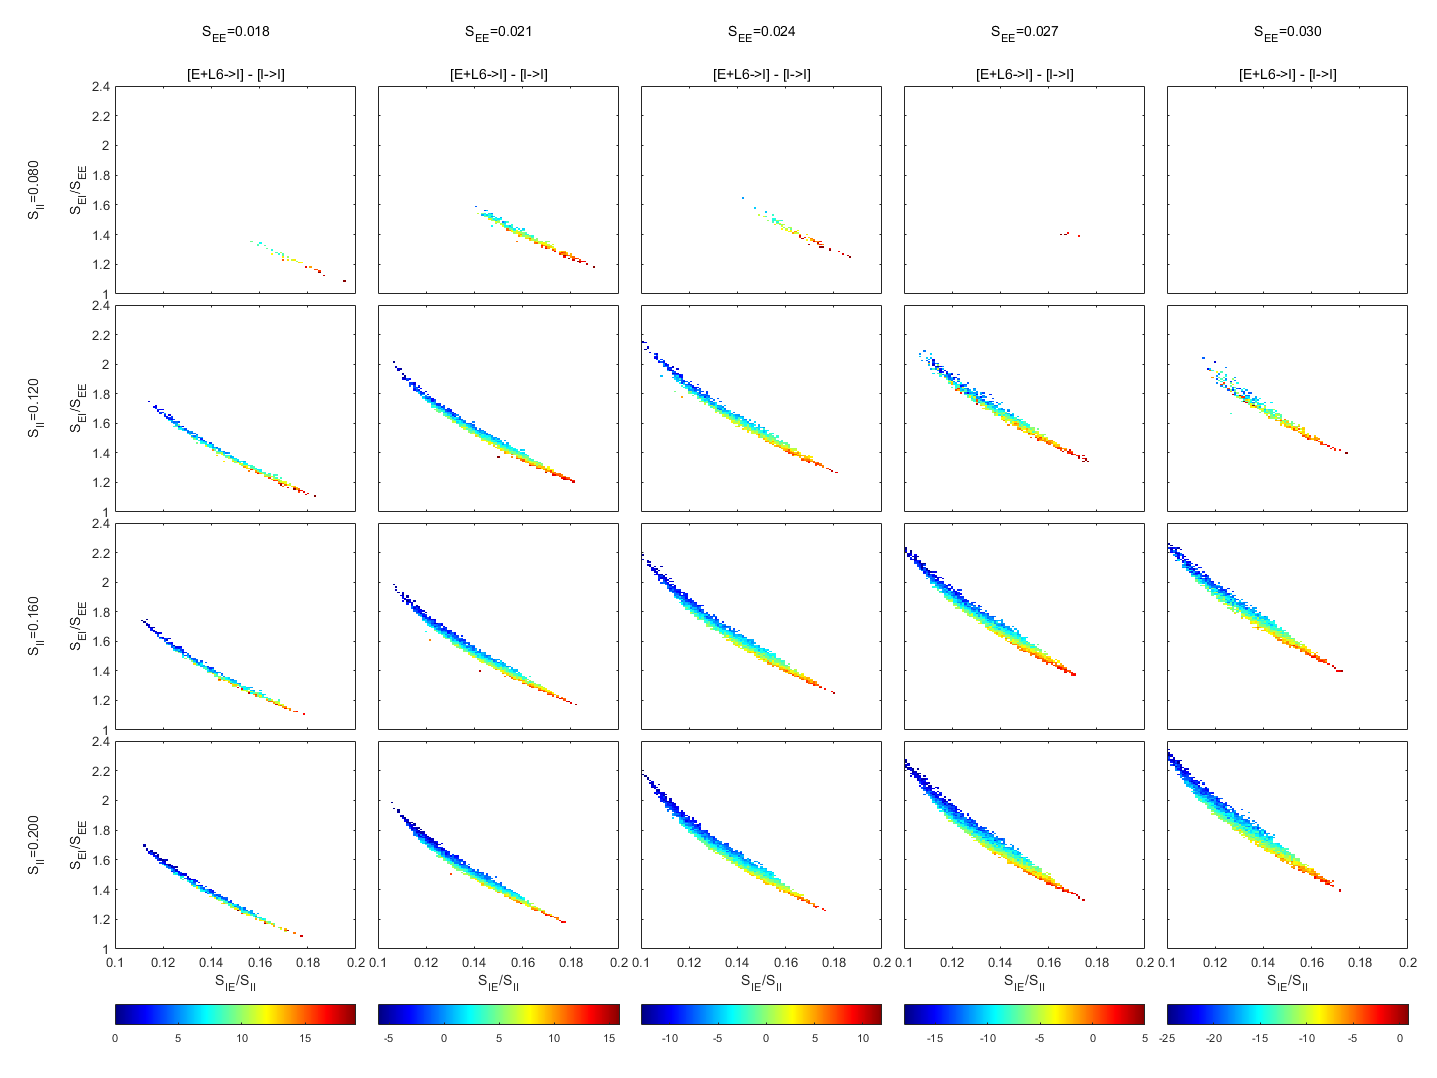

Fig5B = figure('Name','Figure5B_I','units','normalized','outerposition',[0 0 .75 1]);
ha2 = tight_subplot(Panel1,Panel2,[.01 .015],[.12 .08],[.08 .02]);
ColorLim = [0  -6 -13 -18 -25 
            19 16 12  5   1];

for S_EEInd = 1:length(S_EEtest)
    for S_IIInd = 1:length(S_IItest)
        % DEtermine dependent parameters
        S_EE = S_EEtest(S_EEInd);
        S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
        S_Elgn=S_Elgntest(S_ElgnInd);
        
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
            S_EE,     S_II,     S_ElgnInd,            S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        
        FrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        FrE(FrE<=0) = 0;
        FrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        FrI(FrE<=0) = 0;
        mVE = squeeze(ContourData_7D.mV_NoFix(1,:,: )); %FrE(FrE<eps) = nan;
        mVE(FrE<=0) = 0;
        mVI = squeeze(ContourData_7D.mV_NoFix(2,:,: ));
        mVI(FrE<=0) = 0;
        Blowup = squeeze(ContourData_7D.FailIndi(:,: ));
        
        GoodAreaInd = FrE>=3 & FrE<=5   & ...
            FrI./FrE    >=3   &   FrI./FrE    <=4.25;
        % Take all values from the field
        unpackStruct(ContourData_7D);
        E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
        [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
        E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
        
        I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
        [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
        I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
        
        N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
        N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));
        
        % A few Ss is indexed to S_IE; and Ref on Fr; so need to prepared in advance
        S_EIMat = repmat(S_EItest',1,length(S_IEtest));
        S_IEMat = repmat(S_IEtest, length(S_EItest),1);
        S_IL6 = 1/3*S_IEMat;
        E_Refac = (1-FrE*tau_ref/1000); E_RefacInv = E_Refac.^-1;
        I_Refac = (1-FrI*tau_ref/1000); I_RefacInv = I_Refac.^-1;
        
        % Compute total conductances
        ENr.EExtCond = (lambda_E*S_Elgn + rE_amb*S_amb)*1000;         % External->E
        ENr.ERecCond = N_EE*S_EE*(1-p_EEFail)*FrE + rE_L6*S_EL6*1000; % E Recurrent->E (L4+L6)
        INr.EExtCond = (lambda_I*S_Ilgn + rI_amb*S_amb)*1000;         % External->I
        INr.ERecCond = N_IE*S_IEMat         .*FrE + rI_L6*S_IL6*1000; % E Recurrent->I (L4+L6)
        
        ENr.ICond    = N_EI*S_EIMat.*FrI;                             % I Recurrent->E (L4)
        INr.ICond    = N_II*S_II    *FrI;                             % I Recurrent->I (L4)
        
        ENr.LCond    = gL_E*1000;
        INr.LCond    = gL_I*1000;
        
        %% This is what it supposed to be!!
        % Compute total current
        ENr.EExtCurr = ENr.EExtCond * (Ve-mVE); % External   ->E
        ENr.ERecCurr = ENr.ERecCond.* (Ve-mVE); % E Recurrent->E (L4+L6)
        ENr.ICurr    = ENr.ICond   .* (Vi-mVE); % I Recurrent->E (L4)
        ENr.LCurr    = ENr.LCond   .* (0 -mVE);
        
        INr.EExtCurr = INr.EExtCond * (Ve-mVI); % External   ->I
        INr.ERecCurr = INr.ERecCond.* (Ve-mVI); % E Recurrent->I (L4+L6)
        INr.ICurr    = INr.ICond   .* (Vi-mVI); % I Recurrent->I (L4)
        INr.LCurr    = INr.LCond   .* (0 -mVI);
        
        %% Sublots
        aa = length(S_EEtest);
        bb = length(S_IItest);
        
               
        %subplot(bb,aa*2,2*S_EEInd+(S_IIInd-1)*2*aa)
        axes(ha2(S_EEInd+Panel2*(S_IIInd-1)));
        I_EminsI = INr.ERecCurr + INr.ICurr;
        I_EminsI(~GoodAreaInd) = nan; I_EminsI(Blowup==1) = nan;
        imagesc(S_IEtest/S_II, S_EItest/S_EE, I_EminsI);
        set(gca,'YDir','Normal')
        %xlabel('S_{IE} as x*S_{II}'); ylabel('S_{EI} as y*S_{EE}')
        cmap = [1,1,1; jet]; colormap(cmap); %colorbar;
        caxis([ColorLim(1,S_EEInd),ColorLim(2,S_EEInd)])        
        axis([0.1 0.2 1 2.4])
        
        % set ticks, labels, titles, etc.
        if S_IIInd == 1
            title({sprintf('S_{EE}=%.3f',S_EE),'','[E+L6->I] - [I->I]'})
        end
        if S_EEInd == 1
            ylabel({sprintf('S_{II}=%.3f',S_II),'','S_{EI}/S_{EE}'})
        else
            set(gca,'yticklabel','')
        end
        if S_IIInd == length(S_IItest)
            Pos1 = get(gca,'Position');
            xlabel('S_{IE}/S_{II}');
            colorbar('southoutside')
            set(gca,'Position',Pos1)
        else
            set(gca,'xticklabel','')
        end
        
    end
end

Save figures

CurrentFolder = pwd;
FigurePaperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'Figure5A_E';
savefig(Fig5A,[FigurePaperpath FigName1 '.fig']);
FigName2 = 'Figure5B_I';
savefig(Fig5B,[FigurePaperpath FigName2 '.fig']);

Print Figs

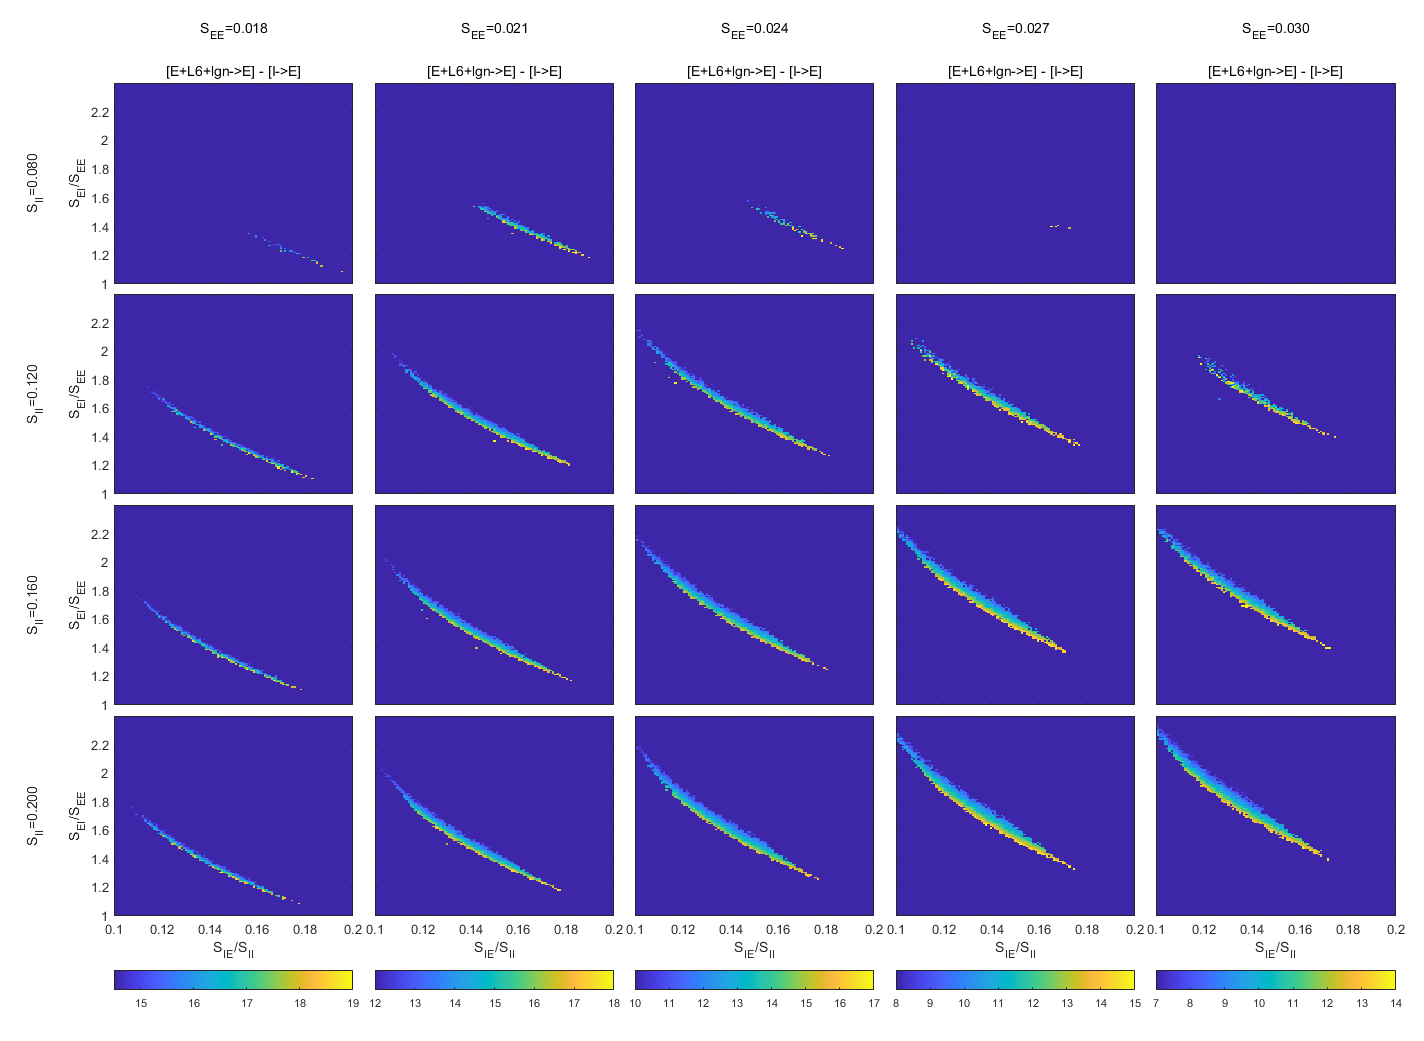

Fig5A.PaperUnits = 'centimeters';
Fig5A.PaperSize = [38,26];
Fig5A.PaperOrientation = "landscape";
exportgraphics(Fig5A,[FigurePaperpath FigName1 '.pdf'],'Resolution',600)


Fig5B.PaperUnits = 'centimeters';
Fig5B.PaperSize = [38,26];
Fig5B.PaperOrientation = "landscape";
exportgraphics(Fig5B,[FigurePaperpath FigName2 '.pdf'],'Resolution',600)